## ECEN415 Assignment 4

#### Niels Clayton: 300437590

### **System Specifications:**

- Achieve an altitude $\left(x_1 \right)$ of at least 1500m 

- Achieve a vertical velocity $\left(x_2 \right)$ of as large as possible 

- Achieve a downrange position $\left(x_3 \right)$ between 50m & 100m 

- Achieve a downrange velocity $\left(x_4 \right)$ of 20m/s

- Achieve a pitch $\left(x_5 \right)$ of ${10}^{\circ }$ & pitch rate $\left(x_6 \right)$ of $0^{\circ }$/s

- No fule remaining $\left(x_7 \right)$

### **Changes to the model:**

The initial mathmatical model of the rocket only functioned correctly for positive inputs $\mathit{\mathbf{u}}$, limiting the rocket to upwards motion and clockwise rotation. This had the effect of 'refulling' the rocket when negative inputs were used. Because of this, the fule consumtopn equation was altered to allow for negative ${\mathit{\mathbf{u}}}_2$ values and anti-clockwise rotations. The final model equation was as follows: 


$$x_7 =\frac{-1}{\eta }\cdot \left(u_1 +|u_2 |\right)$$


### **Approach: **

**Open Loop Control - Static**

Initially, to gain understanding of how the system responds to varying inputs, an 'open loop' controller was designed. This open loop controller worked by simply setting the two inputs $u_1$ and $u_2$ to predefined values at varying time steps. The basic code, aswell as the performance of this controller can be seen below. 

This controller provided us with a baseline performance for the rocket to achieve. The current states of the rocket $\left(\mathit{\mathbf{x}}\right)$ at each controller timestep were also recorded and saved for use in further controllers as possible target locations for these controllers to achieve. These states were saved as the matrix $x_{\textrm{target}}$ and saved in "x_target.mat".

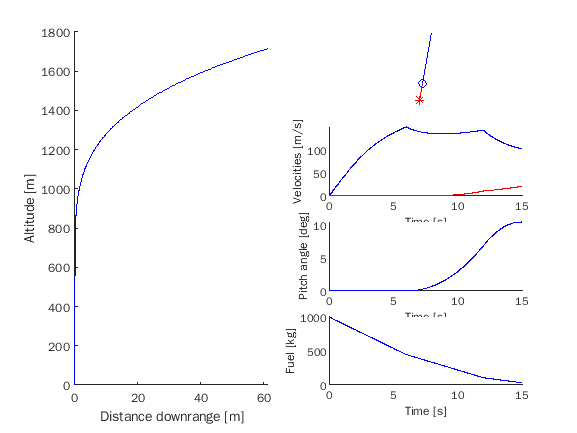

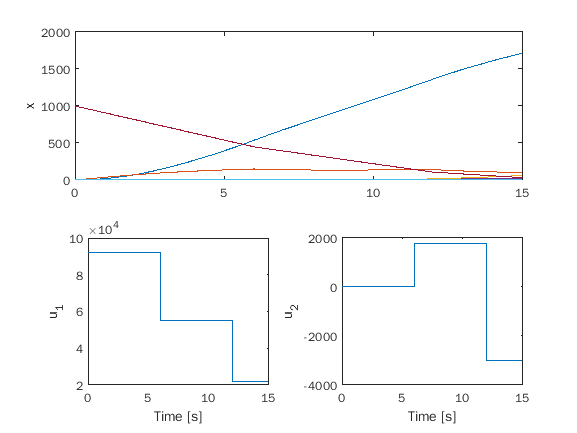

clc; clear;
global linearisation open_loop_control

linearisation = false;
open_loop_control = true;

run("rocket_sim.m");
altitude = x(1);
vel_vert = x(2);
distance = x(3);
vel_horiz = x(4);
pitch = x(5);
pitch_rate = x(6);
fuel = x(7);

final_x = 1×7 table
    altitude    vel_vert    distance    vel_horiz    pitch     pitch_rate    fuel 
    ________    ________    ________    _________    ______    __________    _____

     1713.7      101.57      61.393      20.722      10.415    -0.072836     32.26


final_x = table(altitude,vel_vert,distance,vel_horiz,pitch,pitch_rate,fuel)

**Open Loop Control - Dynamic**

Next, a more dynamic open loop controller was attempted. This controller linearises the non-linear rocket model using Jacobians to calculate ${\textrm{Df}}_x$ and ${\textrm{Df}}_u$. Usinging these Jacobians, the system is linearised at each time step, substituting in the current rocket state and inputs to generate the state space matrices $\mathit{\mathbf{A}}$ and $\mathit{\mathbf{B}}$.

Using these matrices, the equation for the next required $u$ to achieve a given $x_{\textrm{target}}$ was derived from the following equations:


$$\dot{x} =\mathit{\mathbf{A}}\cdot x+\mathit{\mathbf{B}}\cdot \;u$$



$$x_{\textrm{target}} =\dot{x} +x$$


If we rearrange these we get the following equation for the required $u$:


$$u={\mathit{\mathbf{B}}}^{-1} \left(x_{\textrm{target}} -x-\mathit{\mathbf{A}}\cdot x\right)$$


Using this equation, a controller was designed to take the linearised state space system as well as a target state, and provide the required inputs to achieve that state. 

This posed the problem of requiring knowledge of how we want to system to respond, and what sutible target states are for the controller. 

Initially, the system states of the static open loop controller were utilised as the target states for this controller. This however did not function as expected, and the final state of the system varied greatly from the targeted values. To resolve this, the target states for this controler were set to be a linear interpolation between some initial values and some final target state. This was found to be very dificult to tune, most likely due to the uninvertable nature of the 'thin' $\mathit{\mathbf{B}}$ matrix requiring the use of the pseudo-inverse approximation. 

Despite this a controller was tuned to closely meets the specified requrments, and it's performance can be seen in the figureas and tables below.

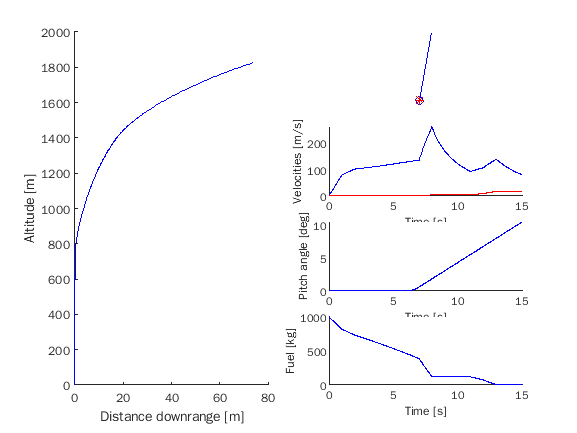

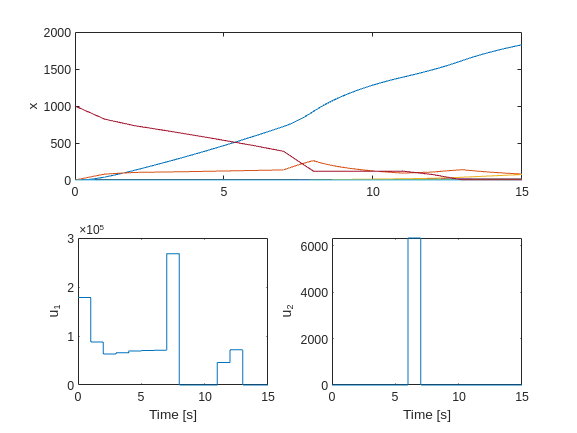

clc; clear;
global linearisation open_loop_control

linearisation = true;
open_loop_control = true;

run("rocket_sim.m");

altitude = x(1);
vel_vert = x(2);
distance = x(3);
vel_horiz = x(4);
pitch = x(5);
pitch_rate = x(6);
fuel = x(7);
final_x = table(altitude,vel_vert,distance,vel_horiz,pitch,pitch_rate,fuel)

final_x = 1×7 table
    altitude    vel_vert    distance    vel_horiz    pitch     pitch_rate     fuel 
    ________    ________    ________    _________    ______    __________    ______

     1826.7       80.5       74.084      18.333      10.519      1.2383      2.1439


**Closed Loop Controller**

The final attempted controller for this system is a closed loop gain controller via pole placment. This form of controller also required the linerisation of the system model, and utilised the same Jacobains from the previous controller to produce the $\mathit{\mathbf{A}}$ and $\mathit{\mathbf{B}}$ matrices.

Once the poles are placed, the controller gains will be used to close the loop with the following equation:


$$u=-\mathit{\mathbf{K}}\left(x-x_{\textrm{target}} \right)$$


The first challenge with this controller design was the placment of the system poles. As this system is not time invariant, the optimal pole locations and thereby controller gains are not contant. Due to this, the use of the matlab `'place()'` command was not feseable, as the optimal locations for all system poles at each given time-step would be very tedious to calculate. 

To overcome this, a static linear quadratic regulator was used to calculate the controller gains at each time step. This controller required inputs $\mathit{\mathbf{A}}$ and $\mathit{\mathbf{B}}$ (the linearised system model) as well as $\mathit{\mathbf{Q}}$ and $\mathit{\mathbf{R}}$. Both the $\mathit{\mathbf{Q}}$ and $\mathit{\mathbf{R}}$ matricies sets bounds on the controller, specifying how much we wish the controller to be able to deviate from our target value, with larger values allowing for larger deviation.

To tune this controller, the selection of input and output bounds must be completed, as well as the selection of the target states for the controller to achieve. Due to the large number of variables to tune for this controller, it was decided that the system state matrix saved from the first controller would be used for the target vlaues, to decrease the number of parameters. From here the bounds were tuned on a basis of which final states were deemed to be most important for the controller to achieve. In the case of this controller, emphasis was placed on both the pitch angle and pitch rate of the rocket, allowing for more deviation in the final state of the fuel. 

The final tuned controller can be seen operating below. Due to the emphasis placed achieving the pitch angle and rate, it can be seen that the controller maintains this value. It can also be seen from that table below that the controller closely meets the majory of requirments outlined.

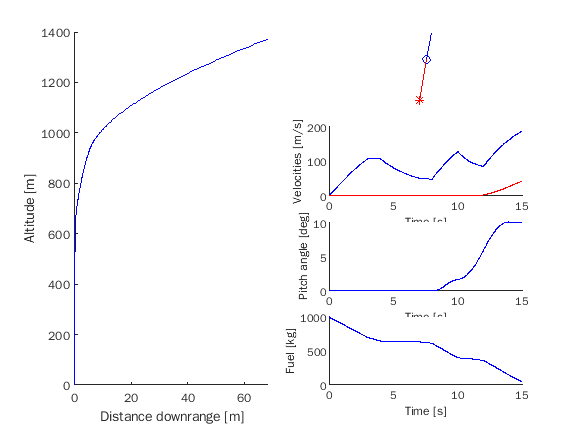

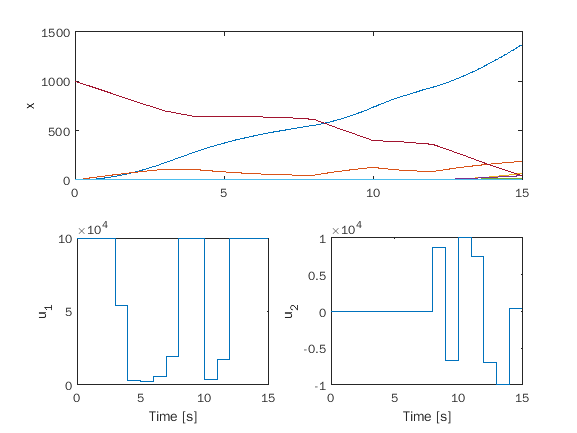

clc; clear;
global linearisation open_loop_control

linearisation = true;
open_loop_control = false;

run("rocket_sim.m");

altitude = x(1);
vel_vert = x(2);
distance = x(3);
vel_horiz = x(4);
pitch = x(5);
pitch_rate = x(6);
fuel = x(7);
final_x = table(altitude,vel_vert,distance,vel_horiz,pitch,pitch_rate,fuel)

final_x = 1×7 table
    altitude    vel_vert    distance    vel_horiz    pitch     pitch_rate    fuel 
    ________    ________    ________    _________    ______    __________    _____

     1372.2      188.29      68.44       43.486      10.121    -0.002338     43.97


### Conclusions

Both open loop and closed loop controllers have been designed to meet the outlined specifications for this system. 

It can clearly be seen from the system plots above that the initial open loop controllers provides the best response in regard to both the final state of the system, and the path taken. This controller however implements no form of feedback, and as such has no method of correcting for external perterbances.

Although both the dynamic open loop and closed loop controllers achieved the majority of system requirments, the tuning of the controllers was complex and tedious. However, the closed loop controller intergrates feedback into the system and may allow for the rejection/correction of external errors. 

Overall, of the three controllers disigned and discussed, the static open loop controller provides the best response and easiest implementaion for a system with no external forces, while the closed loop controller provides a more robust controller design.